# Quickstart: Accessing Two-Photon Calcium Imaging Data from the Allen Brain Observatory "Visual Behavior" Dataset

This short example demonstrates the basics of exploring and examining items within the Visual Behavior 2P dataset [1] from the Allen Brain Observatory [2]. For more details on how to use the Brain Observatory Toolbox, see also the [VisualCodingOphysQuickstart](matlab:open('../../quickstarts/OphysQuickstart.mlx'))

## List Available Sessions of the Visual Behavior Dataset

sessionTable = bot.listSessions("VisualBehavior", "Ophys")

sessionTable = 703×29 table
       id        behavior_session_id    mouse_id                                   ophys_container_id                                   ophys_session_id    imaging_plane_group_count          session_type           behavior_type     prior_exposures_to_session_type    age_in_days    equipment_name    experience_level    image_set    indicator    num_depths_per_area    num_targeted_structures    prior_exposures_to_image_set    prior_exposures_to_omissions          project_code          session_number    sex    targeted_structure_acronyms                     full_genotype       

Just like for the **Visual Coding** dataset, all the sessions of the **Visual Behavior** dataset are presented in a table. At the moment of writing this live script, the dataset included 703 ophys sessions. But it is also possible to retrieve behavior-only sessions by including an option in the `bot.listSessions()` function:

sessionTableAll = bot.listSessions("VisualBehavior", "Ophys", "IncludeBehaviorOnly", true)

sessionTableAll = 4782×37 table
       id        behavior_session_id    file_id    mouse_id    ophys_container_id    ophys_session_id    imaging_plane_group_count    go_trial_count    false_alarm_trial_count    engaged_trial_count    trial_count    hit_trial_count    correct_reject_trial_count    catch_trial_count    miss_trial_count                session_type                  behavior_type     prior_exposures_to_session_type    age_in_days    equipment_name    experience_level    image_set    indicator    num_depths_per_area    num_targeted_structures    prio

This table includes the ophys sessions listed before but it also includes behavior-only sessions which does not have any associated calcium imaging data. If the `ophys_session_id` equals 0, the session is a behavior-only session.

### List All of the Unique Session Types

ophysUniqueSessionTypes = unique(sessionTable.session_type)

ophysUniqueSessionTypes = 18×1 categorical array
     OPHYS_1_images_A 
     OPHYS_1_images_B 
     OPHYS_1_images_G 
     OPHYS_2_images_A_passive 
     OPHYS_2_images_B_passive 
     OPHYS_2_images_G_passive 
     OPHYS_3_images_A 
     OPHYS_3_images_B 
     OPHYS_3_images_G 
     OPHYS_4_images_A 
     OPHYS_4_images_B 
     OPHYS_4_images_H 
     OPHYS_5_images_A_passive 
     OPHYS_5_images_B_passive 
     OPHYS_5_images_H_passive 
     OPHYS_6_images_A 
     OPHYS_6_images_B 
     OPHYS_6_images_H 


allUniqueSessionTypes = unique(sessionTableAll.session_type)

allUniqueSessionTypes = 41×1 categorical array
     OPHYS_0_images_A_habituation 
     OPHYS_0_images_B_habituation 
     OPHYS_0_images_G_habituation 
     OPHYS_1_images_A 
     OPHYS_1_images_B 
     OPHYS_1_images_G 
     OPHYS_2_images_A_passive 
     OPHYS_2_images_B_passive 
     OPHYS_2_images_G_passive 
     OPHYS_3_images_A 
     OPHYS_3_images_B 
     OPHYS_3_images_G 
     OPHYS_4_images_A 
     OPHYS_4_images_B 
     OPHYS_4_images_H 
     OPHYS_5_images_A_passive 
     OPHYS_5_images_B_passive 
     OPHYS_5_images_H_passive 
     OPHYS_6_images_A 
     OPHYS_6_images_B 
     OPHYS_6_images_H 
     TRAINING_0_gratings_autorewards_15min 
     TRAINING_1_gratings 
     TRAINING_2_gratings_flashed 
     TRAINING_3_images_A_10uL_reward 
     TRAINING_3_images_B_10uL_reward 
     TRAINING_3_images_G_10uL_reward 
     TRAINING_4_images_A_handoff_lapsed 
     TRAINING_4_images_A_handoff_ready 
     TRAINING_4_images_A_training 


The Visual Behavior dataset is longitudinal study and the mice go through many stages (or session types), both during behavioral training and during imaging. For more details about the available session types see [this section](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/visual_behavior_ophys_dataset_manifest.html#Session-Type---a-very-important-piece-of-information) from the Allen SDK tutorials.

## Examine Session Items

session = bot.getSessions( sessionTable(5,:) )

session =   OphysSession (VisualBehavior) with properties:

                        id: 957020350
                      info: [1×1 struct]
               SessionType: OPHYS_4_images_B
           LinkedFilesInfo: dictionary (string ⟼ string) with 1 entry

   Linked Items
                Experiment: [1×7 bot.behavior.item.Experiment]
                     Cells: [78×4 table]

   Linked File Values ('BehaviorNWB')
                  Metadata: [1x1 struct]              (on-demand)
            SubjectDetails: [1x1 struct]              (on-demand)
            TaskParameters: [1x1 struct]              (on-demand)
    EyeTrackingRigGeometry: [1x1 struct]              (on-demand)
                     Licks: [2846x1 timetable]        (on-demand)
                   Rewards: [75x2 timetable]          (on-demand)
               EyeTracking: [136505x15 timetable]     (on-demand)
              RunningSpeed: [269871x1

If you are familiar with the **Visual Coding** ophys sessions you might notice that this session looks a bit different. First of all, property names are written in PascalCase, to be more MATLAB-like. Second, even if the data is not available, the property value indicates the expected data type and size. Lastly, there is no ophys data (i.e Fluorescence traces) available on the session item. This is because the imaging was performed across multiple FOVs for many of the mice, and the ophys data is instead available through `Experiment` items, where one `Experiment` represents one imaging plane. For more info, see [this illustration](https://allensdk.readthedocs.io/en/latest/_static/visual_behavior_2p/data_structure.png) (Note: The definition of an `Experiment` item is different than in the **Visual Coding** dataset.

## Examine Experiment Items

The session we looked at above has 7 linked `Experiment` items:

session.Experiment

ans =   1×7 Experiment array (VisualBehavior)

    Experiment (957759562) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (957759564) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (957759566) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (957759570) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (957759572) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (957759574) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (957759576) of type "OPHYS_4_images_B" [Data Available]


Let's look at one of them:

experiment = session.Experiment(1)

experiment =   Experiment (VisualBehavior) with properties:

                             id: 957759562
                           info: [1×1 struct]
                    SessionType: OPHYS_4_images_B
                LinkedFilesInfo: dictionary (string ⟼ string) with 1 entry

   Linked Items
                      Container: [6×32 table]
                        Session: [1×1 bot.behavior.item.OphysSession]
                          Cells: [8×4 table]

   Linked File Values ('OphysNWB')
            TwoPhotonParameters: [1x1 struct]              (on-demand)
              CellSpecimenTable: [8x13 table]              (on-demand)
           FovAverageProjection: [512x512 uint8]           (on-demand)
           FovMaximumProjection: [512x512 uint8]           (on-demand)
          SegmentationMaskImage: [512x512 int64]           (on-demand)
      FluorescenceTracesDemixed: [48284x1 timetable]       (on-demand)


The `Experiment` item contains many of the same properties as the `Session`, but it also has a set of ophys-specific properties. Additionally, it has a set of linked items called a `Container`, and this will be a link to Experiments from the same imaging plane taken at different sessions (more on this later).

### Request a Property Value to Trigger Download of the NWB Data

Currently the data is not available, but upon requesting a property value, the data will be downloaded:

metadata = experiment.Metadata

metadata = struct with fields:
            institution: "Allen Institute for Brain Science"
                devices: [0×0 string]
            description: "2-photon calcium imaging in the visual cortex of the mouse brain as the mouse performs a visual change detection task with natural scene images that are unique from those on which the mouse was trained prior to the imaging phase of the experiment. Image stimuli are displayed for 250 ms with a 500 ms intervening gray period. 5% of non-change image presentations are randomly omitted. The session is 75 minutes long, with 5 minutes of gray screen before and after 60 minutes of behavior, followed by 10 repeats of a 30 second natural movie stimulus at the end of the session."
    session_description: "OPHYS_4_images_B"
     session_start_time: 27-Sep-2019 08:58:37
               keywords: ["2-photon"    "calcium imaging"    "visual cortex"    "behavior"    "task"]
     allen_project_code: 'VisualBehaviorMultiscope'
         equipment_name

### Check Out the Experiment Again

The experiment display is updated to show the size and availability of the NWB Data. Note that the Metadata is now in memory.

experiment

experiment =   Experiment (VisualBehavior) with properties:

                             id: 957759562
                           info: [1×1 struct]
                    SessionType: OPHYS_4_images_B
                LinkedFilesInfo: dictionary (string ⟼ string) with 1 entry

   Linked Items
                      Container: [6×32 table]
                        Session: [1×1 bot.behavior.item.OphysSession]
                          Cells: [8×4 table]

   Linked File Values ('OphysNWB')
            TwoPhotonParameters: [1x1 struct]              (on-demand)
              CellSpecimenTable: [8x13 table]              (on-demand)
           FovAverageProjection: [512x512 uint8]           (on-demand)
           FovMaximumProjection: [512x512 uint8]           (on-demand)
          SegmentationMaskImage: [512x512 int64]           (on-demand)
      FluorescenceTracesDemixed: [48284x1 timetable]       (on-demand)


### View the FOV Average Projection Image

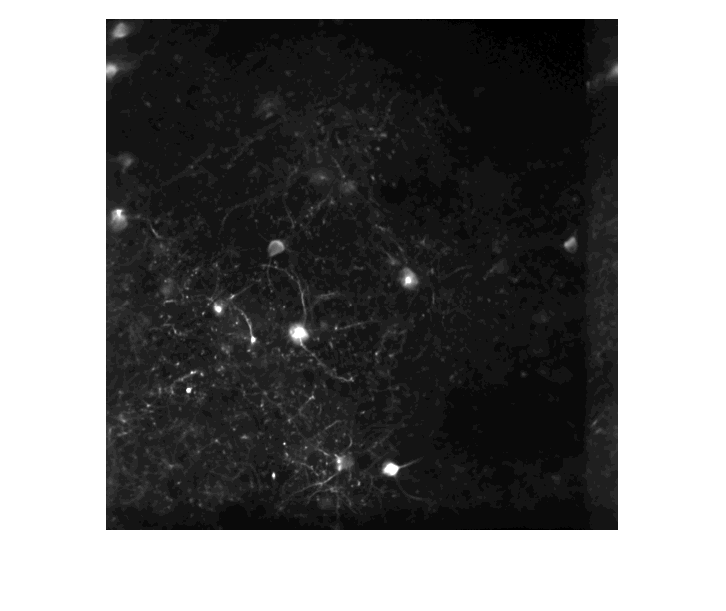

avgImage = experiment.FovAverageProjection;
avgImage = imadjust(avgImage, stretchlim(avgImage,[0.001, 0.999]));
f=figure; ax = axes(f); imshow(avgImage, 'Parent', ax)

### Examine the Cell Specimen Table

experiment.CellSpecimenTable

ans = 8×13 table
    cell_specimen_id    cell_roi_id    height    mask_image_plane    max_correction_down    max_correction_left    max_correction_right    max_correction_up    valid_roi    width     x      y         roi_mask     
    ________________    ___________    ______    ________________    ___________________    ___________________    ____________________    _________________    _________    _____    ___    ___    _________________

       1086614149       1080740882       16             0                     5                     25          

If you scroll to the right most column you'll see that this table contains roi masks for each cell

### Plot the Outlines of the Rois Overlaid on the Average Projection Image

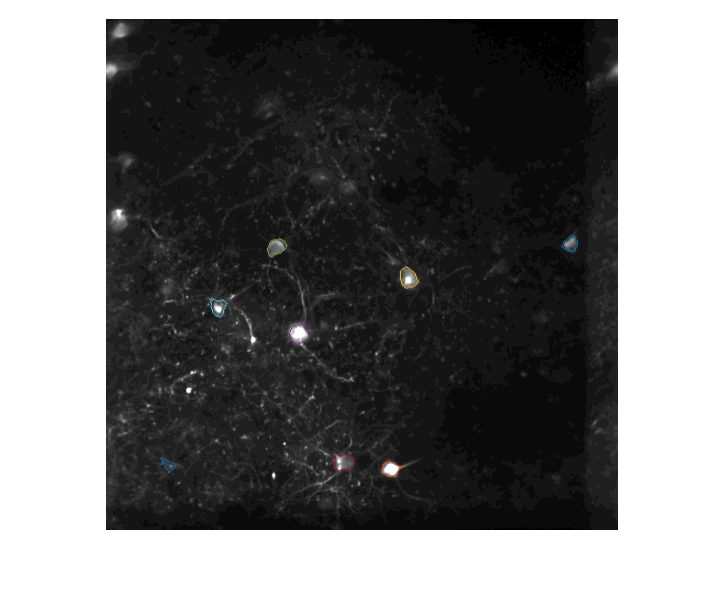

% Get and plot outlines of roi masks. 
f=figure(); ax = axes(f); imshow(avgImage, 'Parent', ax)
hold(ax, 'on')

roiMasks = experiment.CellSpecimenTable.roi_mask;
plotRoiOutlines(ax, roiMasks)

### View and Plot DFF traces

dff = experiment.FluorescenceTracesDFF

dff = 48284×1 timetable
    timestamps    FluorescenceTracesDFF
    __________    _____________________

    8.7247 sec         1×8 double      
    8.8179 sec         1×8 double      
    8.9111 sec         1×8 double      
    9.0043 sec         1×8 double      
    9.0975 sec         1×8 double      
    9.1907 sec         1×8 double      
    9.2839 sec         1×8 double      
    9.3771 sec         1×8 double      
    9.4703 sec         1×8 double      
    9.5635 sec         1×8 double      
    9.6567 sec         1×8 double      
    9.7499 sec         1×8 double      
    9.8431 sec         1×8 double      
    9.9363 sec         1×8 double      
    10.029 sec

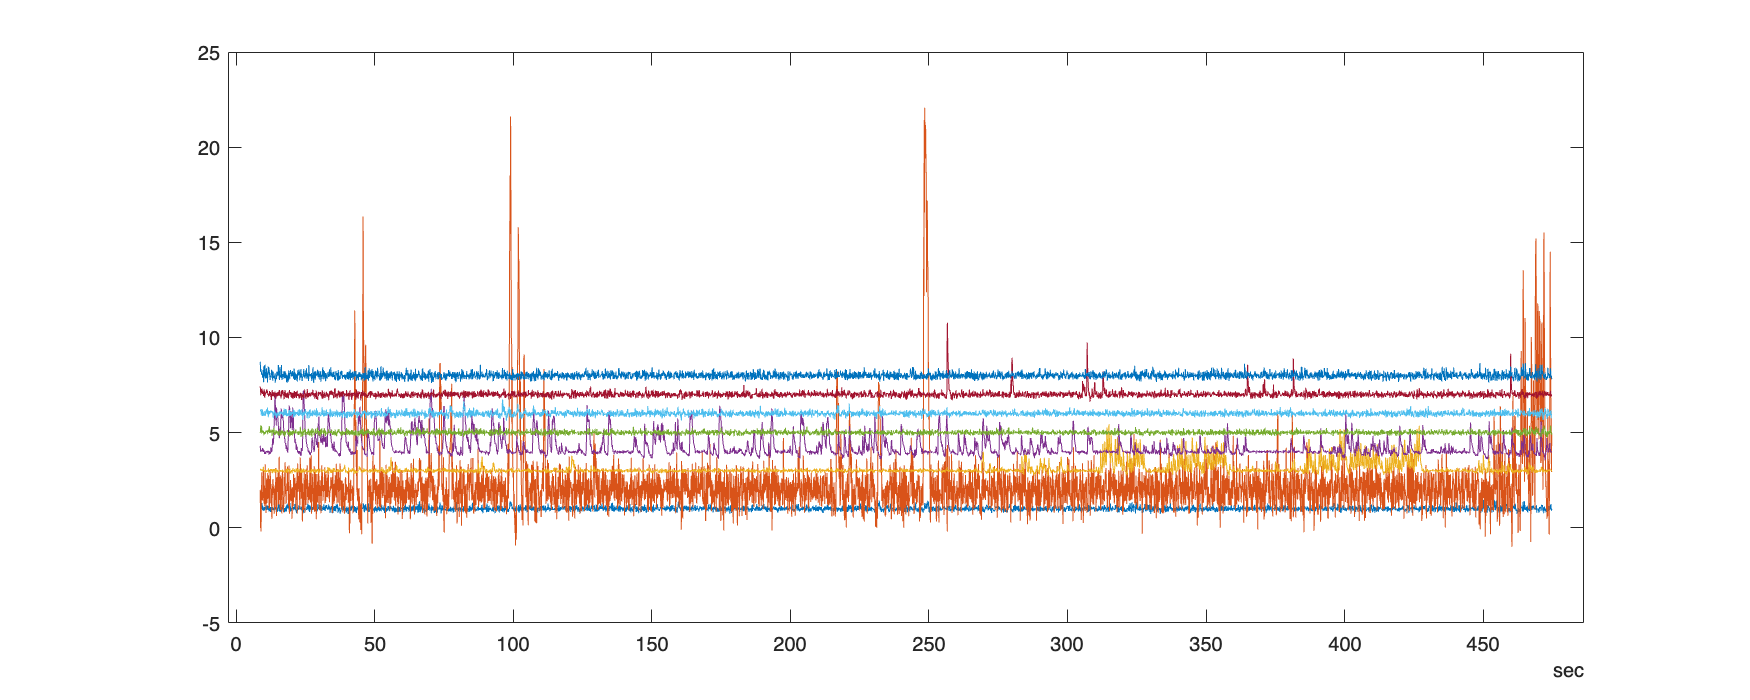

dffMatrix = dff.FluorescenceTracesDFF;
numCells = size(dffMatrix, 2);
dffMatrix = dffMatrix + (1:numCells); % Offset each line by 1 unit
f=figure('Position',[1,1,1000,400]); 
ax = axes(f);

% Plot the first 5000 samples for maximum 50 rois
plot(dff.timestamps(1:5000), dffMatrix(1:5000, 1:min([50, size(dffMatrix,2)])))

### Retrieve and Plot Behavioral Data Variables

licks = experiment.Licks;
rewards = experiment.Rewards;
running_speed = experiment.RunningSpeed;

All the behavioral variables are available as timetables. That makes it easy to plot them on the same time base:

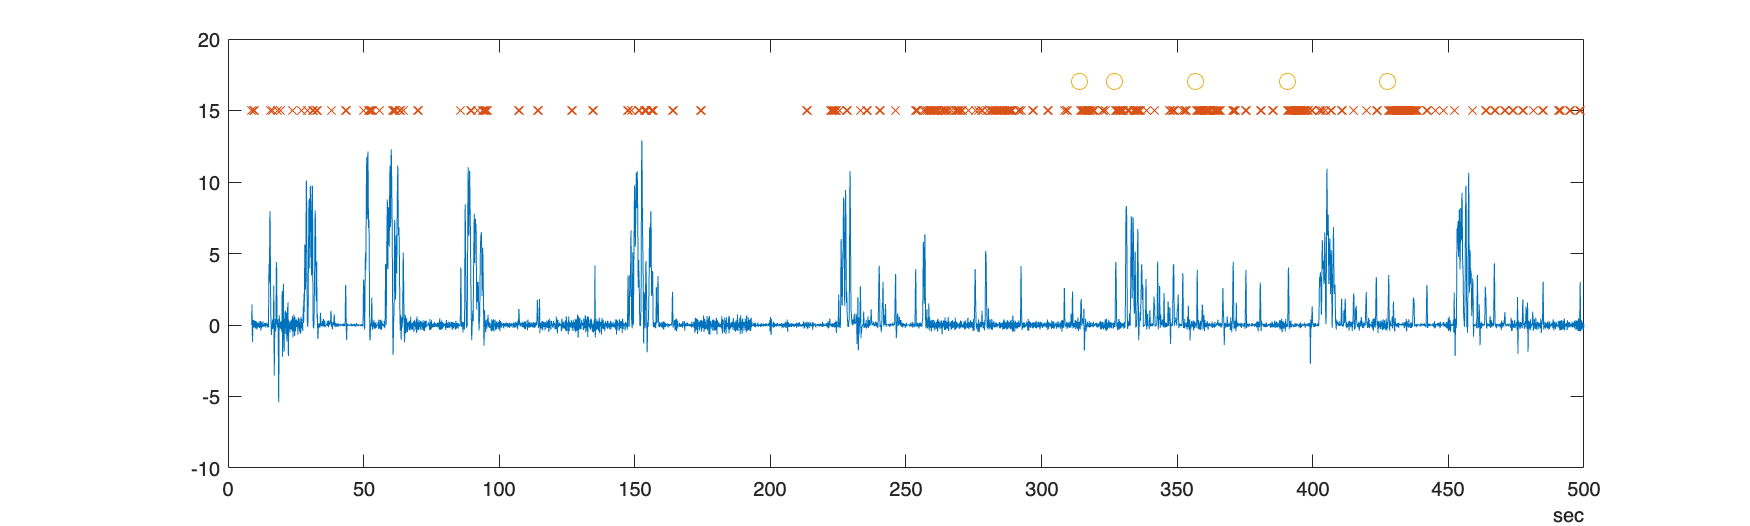

f=figure('Position',[1,1,1000,300]);
ax = axes(f);
plot(running_speed.timestamps, running_speed.speed)
hold(ax, 'on')
plot(licks.timestamps, 15*ones(size(licks.timestamps)), 'x')
plot(rewards.timestamps, 17*ones(size(rewards.timestamps)), 'o', 'MarkerSize', 8)
ax.XLim = seconds([0, 500]);
hold(ax, 'off')

## Examine the Container Item

We can get the Container for the `Experiment` and turn it into `Experiment` items (Note: the Container is not represented by an actual item in BOT, it is just a list of related experiment items):

container = experiment.Container;
experimentCollection = bot.getExperiments(container)

experimentCollection =   1×6 Experiment array (VisualBehavior)

    Experiment (951980471) of type "OPHYS_1_images_A" [Data Available]    
    Experiment (958527464) of type "OPHYS_3_images_A" [Data Available]    
    Experiment (956941841) of type "OPHYS_3_images_A" [Data Available]    
    Experiment (958741219) of type "OPHYS_3_images_A" [Data Available]    
    Experiment (959388788) of type "OPHYS_5_images_B_passive" [Data Available]    
    Experiment (960410023) of type "OPHYS_6_images_B" [Data Available]


This list does not include the original experiment, so lets add it:

experimentCollection = [experiment, experimentCollection]

experimentCollection =   1×7 Experiment array (VisualBehavior)

    Experiment (957759562) of type "OPHYS_4_images_B" [Data Available]    
    Experiment (951980471) of type "OPHYS_1_images_A" [Data Available]    
    Experiment (958527464) of type "OPHYS_3_images_A" [Data Available]    
    Experiment (956941841) of type "OPHYS_3_images_A" [Data Available]    
    Experiment (958741219) of type "OPHYS_3_images_A" [Data Available]    
    Experiment (959388788) of type "OPHYS_5_images_B_passive" [Data Available]    
    Experiment (960410023) of type "OPHYS_6_images_B" [Data Available]


### Plot All the FOVs and ROIs for the Experiments of the Container

In the last section we will try to display all the FOV images from this set of experiments. As the data is stored in NWB files and available from an AWS S3 Bucket, it is possible to access data from the files without downloading the entire files. This is typically much faster if MATLAB is running on a cloud environment, i.e MATLAB Online. Use the checkbox below to control whether you want to try and access the data remotely, or if you want to download all the files:

downloadFiles = false;
prefs = bot.util.getPreferences;
prefs.DownloadRemoteFiles = downloadFiles;
if prefs.DownloadRemoteFiles
    disp('Files will be downloaded')
else
    disp('Files will be accessed remotely')
end

Files will be accessed remotely


Fetch all the average projection images:

[im, rois] = deal( cell(1, numel(experimentCollection)) );

for i = 1:numel(experimentCollection)
    t1 = tic;
    iExp = experimentCollection(i);
    im{i} = iExp.FovAverageProjection;
    rois{i} = iExp.CellSpecimenTable.roi_mask;
    fprintf('Retrieved image and rois for experiment %d in %d seconds.\n', iExp.id, round(toc(t1)))
end

Retrieved image and rois for experiment 957759562 in 0 seconds.
Retrieved image and rois for experiment 951980471 in 0 seconds.
Retrieved image and rois for experiment 958527464 in 0 seconds.
Retrieved image and rois for experiment 956941841 in 4 seconds.
Retrieved image and rois for experiment 958741219 in 4 seconds.
Retrieved image and rois for experiment 959388788 in 3 seconds.
Retrieved image and rois for experiment 960410023 in 3 seconds.


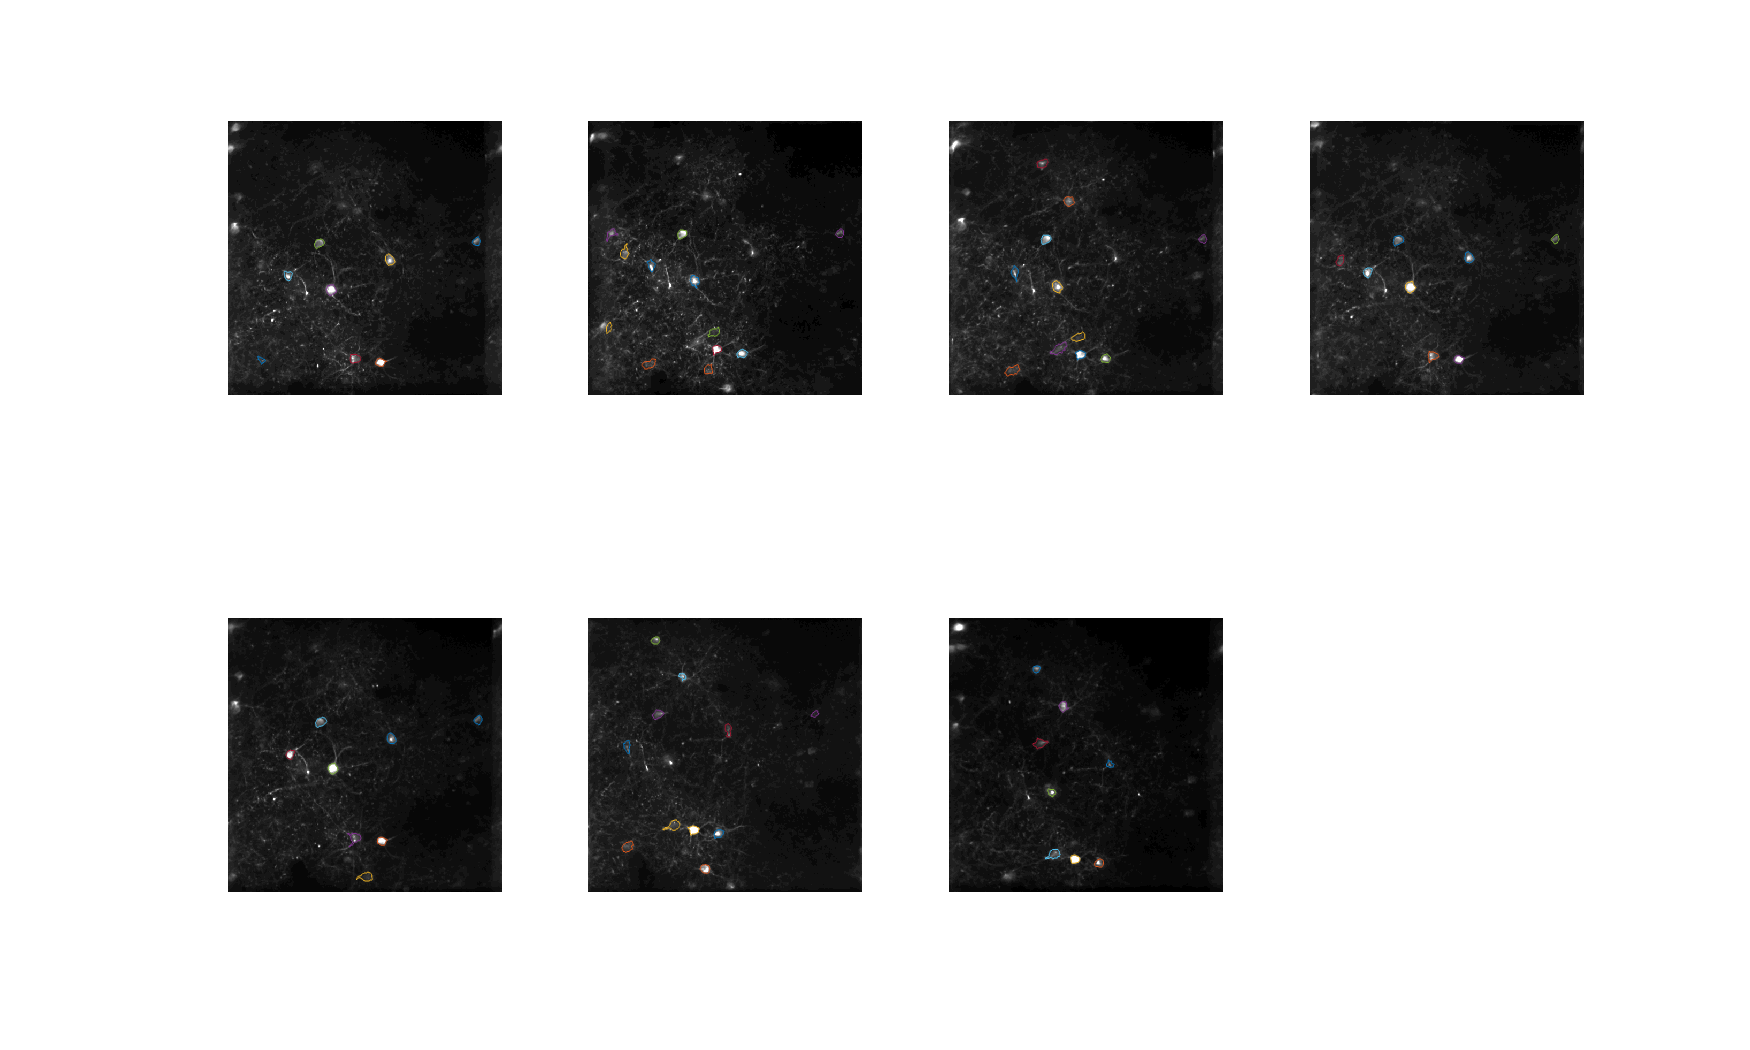

f=figure('Position',[1,1,1000,600]);
for i = 1:numel(im)
    s = subplot(2,4,i, 'Parent', f);
    displayImage = imadjust(im{i}, stretchlim(im{i},[0.001, 0.999]));
    imshow(displayImage, 'Parent', s)
    hold(s, 'on')
    plotRoiOutlines(s, rois{i})
end

Utility function:

function plotRoiOutlines(ax, roiMasks)
    for i = 1:numel(roiMasks)
        B = bwboundaries(roiMasks{i});
        plot(ax, B{1}(:,2), B{1}(:,1)) % Note:  1st column is y-coordinates, 2nd column is x-coordinates
    end
end

### References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Behavior 2P dataset. Available from: [https://portal.brain-map.org/circuits-behavior/visual-behavior-2p](https://portal.brain-map.org/circuits-behavior/visual-behavior-2p).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 